# Problem 3

addpath(genpath(fileparts(which('pathfile.m'))))
interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);
set(groot, 'defaultAxesTickLabelInterpreter',interr);
set(groot, 'defaultLegendInterpreter',interr);

AU = 1.496e+8;
R_E = 6378.1363;
R_V = 6051.9;
R_M = 2439.7;
mu_E = 398600.4415;
mu_V = 324858.59882646;
mu_M = 22032.080486418;
mu_S = 132712440017.99;
a_E = 149597898.0000;
a_V = 108207284.0000;
a_M = 57909101.0000;

## Part a)

launch = 2453221.0000000;
E_encounter = 2453585.0000000;
V_encounter1 = 2454033.0000000;
M_encounter1 = 2454480.0000000;
MOI = 2455639.0000000;
% i
TOF = E_encounter-launch

TOF = 364

% ii
TOF = V_encounter1 - E_encounter

TOF = 448

% iii
TOF = M_encounter1 - launch

TOF = 1259

% iiii
TOF = MOI - launch

TOF = 2418

clear launch TOF E_encounter V_encounter1 M_encounter1 MOI

## Part b)

a_T = 0.8*AU

a_T = 119680000

a_M/a_T

ans = 0.4839

r1_mag = a_E

r1_mag = 149597898

r2_mag = a_V

r2_mag = 108207284


e_T = a_E/a_T - 1

e_T = 0.2500

ta_1 = pi

ta_1 = 3.1416

ta_2 = posangle(-acos(1/e_T * (a_T * (1-e_T^2)/r2_mag - 1))), ta_2_deg = rad2deg(ta_2)

ta_2 = 4.8606

ta_2_deg = 278.4904

E1 = conicanom(ta_1,e_T)

E1 = 3.1416

E2 = conicanom(ta_2,e_T)

E2 = 5.1059

[TOF,dt1,dt2] = timeofflight(ta_1,ta_2,a_T,e_T,r1_mag,mu_S)

TOF = 7.8896e+06

dt1 = 1.1291e+07

dt2 = 1.9180e+07

TOF_day = TOF/3600/24

TOF_day = 91.3148


v_V_mag = sqrt(mu_S/a_V)

v_V_mag = 35.0209

v2_0_mag = sqrt(mu_S*(2/r2_mag - 1/a_T))

v2_0_mag = 36.6611


iCr = [cos(ta_2) -sin(ta_2); sin(ta_2) cos(ta_2)]

iCr =     0.1476    0.9890
   -0.9890    0.1476


h_T = sqrt(mu_S * a_T*(1-e_T^2))

h_T = 3.8588e+09

gamma2_0 = -acos(h_T/r2_mag/v2_0_mag), gamma2_0_deg = rad2deg(gamma2_0)

gamma2_0 = -0.2341

gamma2_0_deg = -13.4113

v2_0_R = v2_0_mag * [sin(gamma2_0);cos(gamma2_0)]

v2_0_R =    -8.5032
   35.6614


v2_0 = iCr * v2_0_R

v2_0 =    34.0151
   13.6752


v_V = iCr * v_V_mag * [sin(0);cos(0)]

v_V =    34.6371
    5.1706



v_inf_0 = v2_0 - v_V

v_inf_0 =    -0.6220
    8.5045


v_inf_mag = norm(v_inf_0)

v_inf_mag = 8.5273


a_h = -mu_V/v_inf_mag^2

a_h = -4.4676e+03

e_h = 1-1.5*R_V/a_h

e_h = 3.0319


delta = 2*(asin(1/e_h)), delta_deg = rad2deg(delta)

delta = 0.6722

delta_deg = 38.5162

eta = pi-asin(v2_0_mag/v_inf_mag * sin(abs(gamma2_0))),eta_deg = rad2deg(eta)

eta = 1.6460

eta_deg = 94.3072

zeta = asin(v_V_mag/v_inf_mag*sin(abs(gamma2_0))),zeta_deg = rad2deg(zeta)

zeta = 1.2616

zeta_deg = 72.2815

zeta+eta+abs(gamma2_0)

ans = 3.1416





v2_n_mag = sqrt(v_V_mag^2 + v_inf_mag^2 - 2*v_V_mag*v_inf_mag*cos(eta-delta))

v2_n_mag = 31.0385

gamma2_n = -asin(v_inf_mag/v2_n_mag * sin(eta-delta)),gamma2_n_deg = rad2deg(gamma2_n)

gamma2_n = -0.2292

gamma2_n_deg = -13.1323


v2_n_R = v2_n_mag*[sin(gamma2_n);cos(gamma2_n)]

v2_n_R =    -7.0520
   30.2268


v2_n = iCr * v2_n_R

v2_n =    28.8543
   11.4375


dv_eq_R = v2_n_R - v2_0_R

dv_eq_R =     1.4512
   -5.4346


dv_eq = v2_n-v2_0

dv_eq =    -5.1607
   -2.2377


dv_eq_mag = norm(dv_eq)

dv_eq_mag = 5.6250


rvs = r2_mag*v2_n_mag^2/mu_S

rvs = 0.7855

e_n = sqrt((rvs-1)^2*cos(gamma2_n)^2+sin(gamma2_n)^2)

e_n = 0.3086

ta2_n = pi+atan((rvs*cos(gamma2_n)*sin(gamma2_n))/(rvs*cos(gamma2_n)^2-1)), ta2_n_deg = rad2deg(ta2_n)

ta2_n = 3.7398

ta2_n_deg = 214.2721

a_n = r2_mag*(1+e_n*cos(ta2_n))/(1-e_n^2)

a_n = 8.9096e+07

ra_n = a_n*(1+e_n)

ra_n = 1.1659e+08

rp_n = a_n*(1-e_n)

rp_n = 6.1598e+07

period = 2*pi/sqrt(mu_S/a_n^3),period_day = period/3600/24

period = 1.4505e+07

period_day = 167.8801

dw = ta2_n - ta_2,dw_deg = rad2deg(dw)

dw = -1.1208

dw_deg = -64.2184

## Part d)

beta = asin(v2_n_mag/dv_eq_mag*sin(gamma2_n-gamma2_0))

beta = 0.0269

beta_deg = rad2deg(beta)

beta_deg = 1.5396

alpha = pi-beta, alpha_deg = rad2deg(alpha)

alpha = 3.1147

alpha_deg = 178.4604

## Part e)

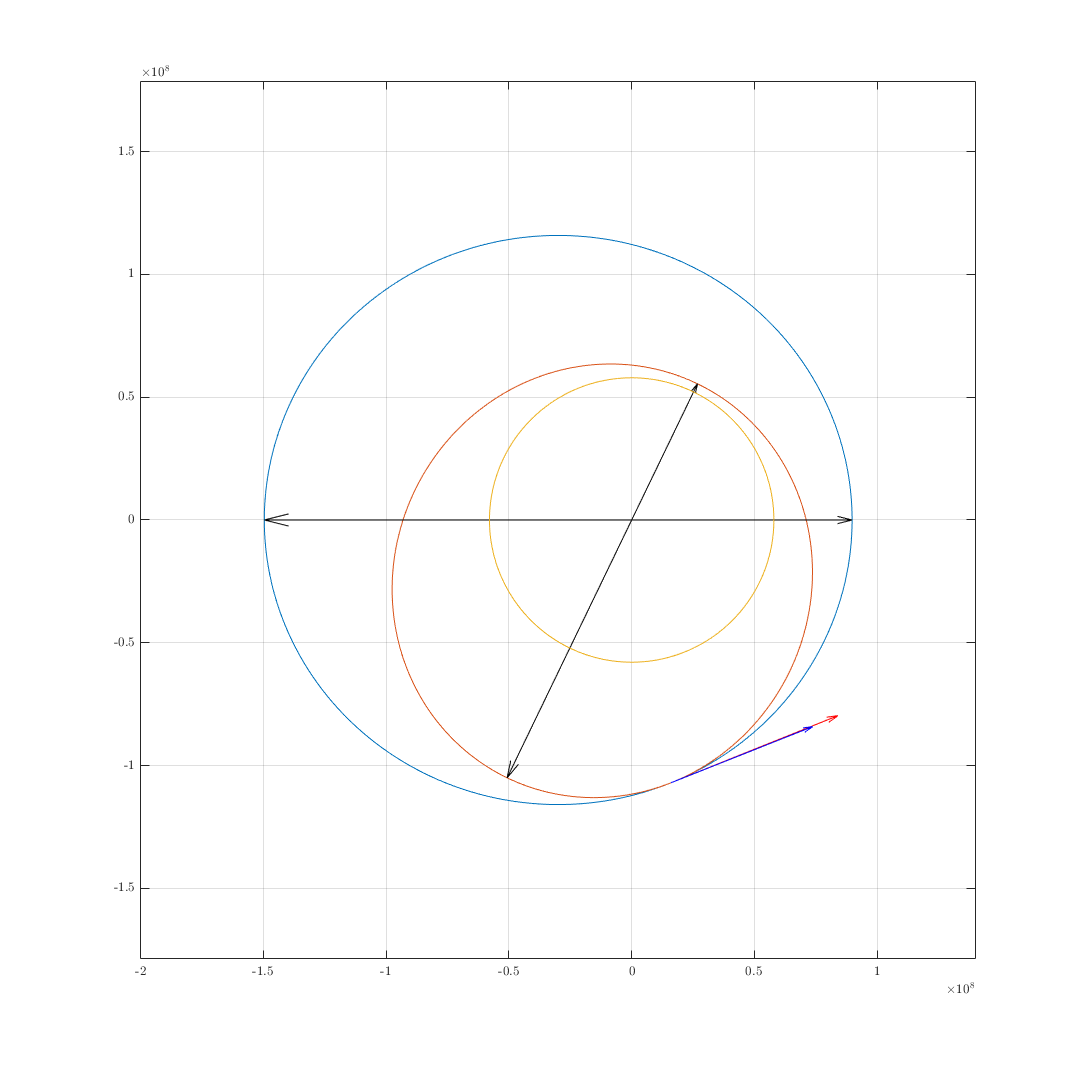

% plotorbit(ai,ei,ths1,ths2,rotate)
% plotvel(a,e,ths,v_R,color,dvoption,angle,scale)
plotorbit(a_T,e_T,0,2*pi,0) % old
hold on
plotorbit(a_n,e_n,0,2*pi,dw) % new
xlim([-1.7 1.2]*1e8)
axis equal
xlim([-2 1.4]*1e8)
plotpos(a_T,e_T,0,'k',0,0) % rp old
plotpos(a_T,e_T,pi,'k',0,0) % ra old
plotpos(a_n,e_n,0,'k',dw,0) % rp new 
plotpos(a_n,e_n,pi,'k',dw,0) % ra new
plotvel(a_T,e_T,ta_2,v2_0,'r',0,0,2e6)
plotvel(a_n,e_n,ta2_n,v2_n,'b',0,dw,2e6)
set(gcf,'position',[0,0,1200,1200])
plotorbit(a_M,0,0,2*pi,0)